## Experiment 6 : Regularization 2

1、插入数据，并绘制点图

x = load ("ex5Logx.dat") ;
y = load ("ex5Logy.dat") ;
figure
% Find t h e i n d i c e s f o r t h e 2 c l a s s e s
pos = find (y) ; neg = find (y == 0) ;
plot ( x(pos ,1) , x(pos,2),'+')
hold on
plot ( x(neg, 1) , x(neg,2),'o') 
xlabel("u"); ylabel("v");
legend(" y = 1"," y = 0")

2、使用2维数据生成28维数据，并使用28维theta，进行正则化牛顿法迭代求theta值

x2 = map_feature(x(:,1), x(:,2));
theta  = zeros(28,1);
m = 117; lamuda = 1;
n  = 28;
for i = 1 : 15
    theta = theta - inv(Hessian(m, lamuda, x2,theta))*J(lamuda, n, m ,theta, x2, y);
end

3、画图（λ = 0，λ = 1，λ = 10）

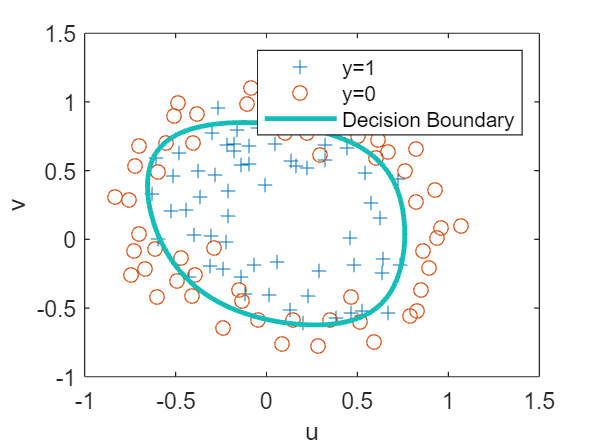

u = linspace(-1, 1.5, 200);
v = linspace(-1, 1.5, 200);
z = zeros(200, 200);
for i = 1 : length(u)
    for j = 1 : length(v)
        z(i,j) = map_feature(u(i), v(j))*theta;
    end
end
z  = z';
contour(u, v, z, [0, 0],'LineWidth',2);
legend('y=1','y=0','Decision Boundary');

4、计算L2 范数

L2 = 0;
for i = 1:28
L2  = L2 + theta(i)*theta(i)
end

L2 = 1.7405

L2 = 2.2458

L2 = 3.6578

L2 = 7.6012

L2 = 8.4642

L2 = 10.7715

L2 = 10.7870

L2 = 10.9219

L2 = 11.0920

L2 = 11.1194

L2 = 13.2957

L2 = 13.2986

L2 = 13.7130

L2 = 13.7919

L2 = 15.2471

L2 = 15.3225

L2 = 15.3650

L2 = 15.3694

L2 = 15.4461

L2 = 15.5446

L2 = 15.7425

L2 = 16.9057

L2 = 16.9064

L2 = 16.9998

L2 = 17.0000

L2 = 17.1117

L2 = 17.1338

L2 = 17.9777

L2 = L2*lamuda/(2*m); 